# Example script illustrating how to fit the a linear pRF model with an anisotropic Gaussian

% This part is identical to pRF_model_example_1_linear and does not need to be rerun

## Add code to the MATLAB path

addpath(genpath(fullfile(pwd,'code')));

## Load data

% load data from the first dataset
load('dataset01.mat','betamn','betase');

## Load stimuli

load('stimuli.mat','conimages');

## Perform stimulus pre-processing

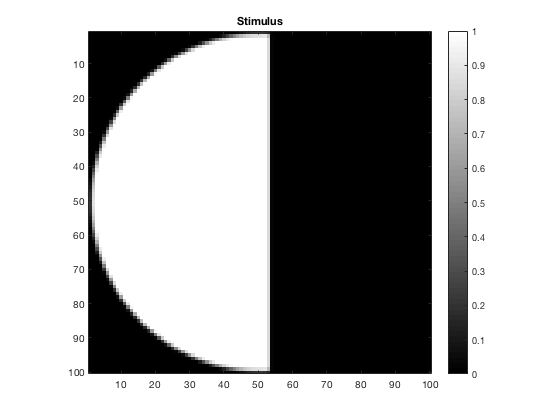

% extract the stimuli we need and then concatenate along the third dimension
stimulus = conimages(1:69);
stimulus = cat(3,stimulus{:});

% resize the stimuli to 100 x 100 (to reduce computational time)
temp = zeros(100,100,size(stimulus,3));
for p=1:size(stimulus,3)
  temp(:,:,p) = imresize(stimulus(:,:,p),[100 100],'cubic');
end
stimulus = temp;

% ensure that all values are between 0 and 1
stimulus(stimulus < 0) = 0;
stimulus(stimulus > 1) = 1;

% inspect one of the stimuli
figure;
imagesc(stimulus(:,:,10));
axis image tight;
colormap(gray);
colorbar;
title('Stimulus');

% reshape stimuli into a "flattened" format: 69 stimuli x 100*100 positions
stimulus = reshape(stimulus,100*100,69)';

## Prepare for model fitting

% the parameters of the Linear Elliptical model are [R C SR G SC] where
%   R is the row index of the center of the 2D Gaussian
%   C is the column index of the center of the 2D Gaussian
%   S is the standard deviation of the 2D Gaussian in rows
%   G is a gain parameter
%   SR is ration of the standard deviations of the 2D Gaussian in the
%           columns to rows

% define constants
res = 100;  % resolution of the pre-processed stimuli

% define the initial seed for the model parameters
seed = [(1+res)/2 (1+res)/2 res 1 1];

% define bounds for the model parameters
bounds = [1-res+1 1-res+1 0   -Inf 0;
          2*res-1 2*res-1 Inf  Inf Inf];

boundsFIX = bounds;
boundsFIX(1,5) = NaN;
      
% issue a dummy call to makegaussian2d.m to pre-compute xx and yy.
% these variables are re-used to achieve faster computation.
[d,xx,yy] = makegaussian2d(res,2,2,2,2);

% we will now define a function that implements the pRF model.  this function
% accepts a set of parameters (pp, a vector of size 1 x 4) and a set of stimuli 
% (dd, a matrix of size A x 100*100) and outputs the predicted response to those 
% stimuli (as a vector of size A x 1).  for compactness, we implement this 
% function as an anonymous function where the parameters are given by pp
% and the stimuli are given by dd.
modelfunElliptical = @(pp,dd) pp(4)*(dd*vflatten(makegaussian2d(res,pp(1),pp(2),pp(3)/pp(5),pp(3)*pp(5),...
    xx,yy,0,0)/(2*pi*pp(3)*pp(5))));

modelfunIsotropic = @(pp,dd) pp(4)*(dd*vflatten(makegaussian2d(res,pp(1),pp(2),pp(3),pp(3),...
    xx,yy,0,0)/(2*pi*pp(3).^2)));

% notice that the overall structure of the model is 
%   RESP = GAIN*(STIM*GAU)
% where STIM*GAU represents the dot product between the stimulus and the 2D Gaussian.
% also, note that the division by (2*pi*pp(3)*pp(5)) makes it such that the integral
% of the Gaussian is equal to 1 (this aids the interpretation of model parameters).

% now that we have defined modelfun, we are ready to define the final model
% specification.  
modelElliptical = {{seed       boundsFIX   modelfunElliptical} ...
         {@(ss) ss   bounds      @(ss) modelfunElliptical}};

     
modelIsotropic  = {seed(1:4) bounds(:,1:4)  modelfunIsotropic};

% define the resampling scheme to use.  here, we use 0, which
% means to just fit the data (no cross-validation nor bootstrapping).
resampling = 0;

% define the metric that we will use to quantify goodness-of-fit.
% here, we use a version of the coefficient of determination (R^2)
% in which variance in the data is computed relative to 0.
% this is sensible since the data being fitted are beta weights that
% represent evoked BOLD responses relative to the baseline signal level
% (which corresponds to 0).
metric = @(a,b) calccod(a,b,[],[],0);

% specify the index of the voxel to fit
ix = 774;

% finally, construct the options struct that will be passed to fitnonlinearmodel.m
optElliptical = struct( ...
  'stimulus',    stimulus, ...
  'data',        betamn(ix,:)', ...
  'model',       {modelElliptical}, ...
  'resampling',  resampling, ...
  'metric',      metric);

optIsotropic = struct( ...
  'stimulus',    stimulus, ...
  'data',        betamn(ix,:)', ...
  'model',       {modelIsotropic}, ...
  'resampling',  resampling, ...
  'metric',      metric);

% do a quick inspection of opt
optElliptical

optElliptical = struct with fields:
      stimulus: [69×10000 double]
          data: [69×1 double]
         model: {{1×3 cell}  {1×3 cell}}
    resampling: 0
        metric: @(a,b)calccod(a,b,[],[],0)


## Fit the model

resultsElliptical = fitnonlinearmodel(optElliptical);

*** fitnonlinearmodel: started at 26-Apr-2018 18:34:10. ***
*** fitnonlinearmodel: outputdir = , chunksize = 1, chunknum = 1
*** fitnonlinearmodel: processing voxel 1 (1 of 1). ***
  starting resampling case 1 of 1.
      for model 1 of 2, the seed is [50.500 50.500 100.000 1.000 1.000 ].

                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          5          85.617                          83.8
     1         10         49.5521             10            9.3      
     2         15         49.5521        12.7774            9.3      
     3         20          45.268        3.19436           13.5      
     4         25          45.268        6.38872           13.5      
     5         30         42.1868        1.59718           8.16      
     6         35         38.2163        3.19436           14.5      
     7         40         38.2163        6.38872           14.5      
     8         45     

resultsIsotropic  = fitnonlinearmodel(optIsotropic);

*** fitnonlinearmodel: started at 26-Apr-2018 18:34:11. ***
*** fitnonlinearmodel: outputdir = , chunksize = 1, chunknum = 1
*** fitnonlinearmodel: processing voxel 1 (1 of 1). ***
  starting resampling case 1 of 1.
      the seed is [50.500 50.500 100.000 1.000 ].

                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          5         109.944                          2.04
     1         10         82.5221             10           23.1      
     2         15         82.5221             20           23.1      
     3         20         47.4414              5           26.3      
     4         25         47.4414             10           26.3      
     5         30         34.0825            2.5             21      
     6         35         24.9808              5           49.1      
     7         40          21.524             10            124      
     8         45         16.7114        8.940

## Inspect the results

% these are the final parameter estimates
resultsElliptical.params

ans =    61.5364   69.9245    4.0745    1.3926    0.8596



% compare to the isotropic fit (highly similar, except that this model is
% elliptical)
resultsIsotropic.params

ans =    61.4024   70.0496    4.1196    6.5934


% this is the R^2 between the model fit and the data
resultsElliptical.trainperformance

ans = 93.3350


% compare to the isotropic fit (highly similar)
resultsIsotropic.trainperformance

ans = 93.2869

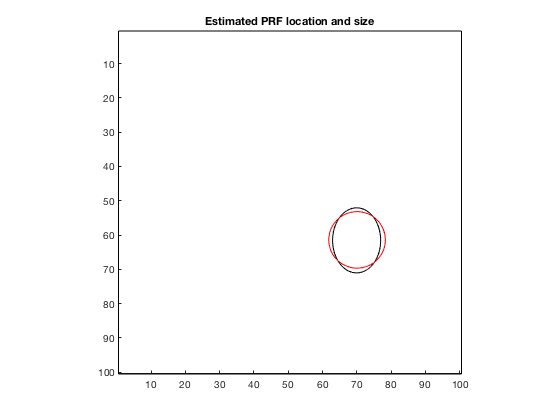

% visualize the parameter estimates
figure; hold on;
pp = resultsElliptical.params;
  % draw a circle indicating the PRF location +/- 2 PRF sizes.
  
drawellipse(pp(2),pp(1),0,2*pp(3)*pp(5),2*pp(3)/pp(5),[],[],'k-');

pp = resultsIsotropic.params;
  % draw a circle indicating the PRF location +/- 2 PRF sizes.
  
drawellipse(pp(2),pp(1),0,2*pp(3),2*pp(3));

drawrectangle((1+res)/2,(1+res)/2,res,res,'k-');
axis([.5 res+.5 .5 res+.5]);
set(gca,'YDir','reverse');
axis square;
title('Estimated PRF location and size');

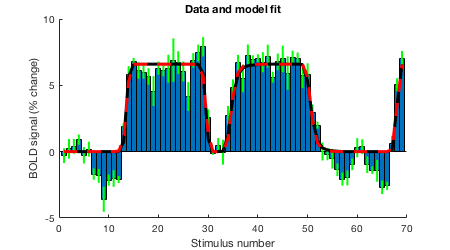

% visualize the data and the model fit
figure; setfigurepos([100 100 450 250]); hold on;
bar(betamn(ix,:),1);
errorbar2(1:69,betamn(ix,:),betase(ix,:),'v','g-','LineWidth',2);

modelfit = modelfunElliptical(resultsElliptical.params,stimulus); % elliptical fit
plot(1:69,modelfit,'k-','LineWidth',3);

modelfit = modelfunIsotropic(resultsIsotropic.params,stimulus);
plot(1:69,modelfit,'r--','LineWidth',3); % isotropic fit

ax = axis;
axis([0 70 ax(3:4)]);
xlabel('Stimulus number');
ylabel('BOLD signal (% change)');
title('Data and model fit');

## Try a different resampling scheme: cross-validation

% define an options struct that specifies leave-one-out cross-validation
optXVAL = optElliptical;
optXVAL.resampling = -2*(eye(69) - 0.5);
optXVAL.optimoptions = {'Display' 'off'};  % turn off reporting

% fit the model
resultsXVALElliptical = fitnonlinearmodel(optXVAL);

*** fitnonlinearmodel: started at 26-Apr-2018 18:34:13. ***
*** fitnonlinearmodel: outputdir = , chunksize = 1, chunknum = 1
*** fitnonlinearmodel: processing voxel 1 (1 of 1). ***
  starting resampling case 1 of 69.
      for model 1 of 2, the seed is [50.500 50.500 100.000 1.000 1.000 ].
      the estimated parameters are [61.403 70.041 4.130 1.596 1.000 ].
      for model 2 of 2, the seed is [61.403 70.041 4.130 1.596 1.000 ].
      the estimated parameters are [61.536 69.924 4.075 1.393 0.860 ].
    trainperformance is 93.34. testperformance is 0.00.
  starting resampling case 2 of 69.
      for model 1 of 2, the seed is [50.500 50.500 100.000 1.000 1.000 ].
      the estimated parameters are [61.403 70.043 4.128 1.597 1.000 ].
      for model 2 of 2, the seed is [61.403 70.043 4.128 1.597 1.000 ].
      the estimated parameters are [61.536 69.924 4.075 1.393 0.860 ].
    trainperformance is 93.34. testperformance is 0.00.
  starting resampling case 3 of 69.
      for model 1 of 2,

% this is the R^2 between the model predictions and the data.
% notice that this cross-validated R^2 is lower than the
% R^2 of the full fit obtained previously.
resultsXVALElliptical.aggregatedtestperformance

ans = 92.0443

## Try a different resampling scheme: bootstrapping

% define an options struct that specifies 25 bootstraps (i.e. draw 
% with replacement from the 69 data points)
optBOOT = optElliptical;
optBOOT.resampling = {25 0};  % the 0 sets the random-number seed to 0
optBOOT.optimoptions = {'Display' 'off'};  % turn off reporting

% fit the model
resultsBOOTElliptical = fitnonlinearmodel(optBOOT);

*** fitnonlinearmodel: started at 26-Apr-2018 18:35:11. ***
*** fitnonlinearmodel: outputdir = , chunksize = 1, chunknum = 1
*** fitnonlinearmodel: processing voxel 1 (1 of 1). ***
  starting resampling case 1 of 25.
      for model 1 of 2, the seed is [50.500 50.500 100.000 1.000 1.000 ].
      the estimated parameters are [61.866 70.478 3.664 1.840 1.000 ].
      for model 2 of 2, the seed is [61.866 70.478 3.664 1.840 1.000 ].
      the estimated parameters are [63.304 72.131 3.048 1.060 0.482 ].
    trainperformance is 93.93. testperformance is NaN.
  starting resampling case 2 of 25.
      for model 1 of 2, the seed is [50.500 50.500 100.000 1.000 1.000 ].
      the estimated parameters are [60.362 71.191 3.205 2.039 1.000 ].
      for model 2 of 2, the seed is [60.362 71.191 3.205 2.039 1.000 ].
      the estimated parameters are [60.435 71.221 3.397 1.690 0.877 ].
    trainperformance is 96.53. testperformance is NaN.
  starting resampling case 3 of 25.
      for model 1 of 2, t


% define an options struct that specifies 25 bootstraps (i.e. draw 
% with replacement from the 69 data points)
optBOOT = optIsotropic;
optBOOT.resampling = {25 0};  % the 0 sets the random-number seed to 0
optBOOT.optimoptions = {'Display' 'off'};  % turn off reporting

% fit the model
resultsBOOTIsotropic = fitnonlinearmodel(optBOOT);

*** fitnonlinearmodel: started at 26-Apr-2018 18:35:34. ***
*** fitnonlinearmodel: outputdir = , chunksize = 1, chunknum = 1
*** fitnonlinearmodel: processing voxel 1 (1 of 1). ***
  starting resampling case 1 of 25.
      the seed is [50.500 50.500 100.000 1.000 ].
      the estimated parameters are [61.866 70.477 3.664 6.740 ].
    trainperformance is 93.51. testperformance is NaN.
  starting resampling case 2 of 25.
      the seed is [50.500 50.500 100.000 1.000 ].
      the estimated parameters are [60.362 71.190 3.206 6.536 ].
    trainperformance is 96.51. testperformance is NaN.
  starting resampling case 3 of 25.
      the seed is [50.500 50.500 100.000 1.000 ].
      the estimated parameters are [61.558 69.283 3.774 6.394 ].
    trainperformance is 93.72. testperformance is NaN.
  starting resampling case 4 of 25.
      the seed is [50.500 50.500 100.000 1.000 ].
      the estimated parameters are [60.256 71.099 2.767 6.615 ].
    trainperformance is 93.34. testperformance is 

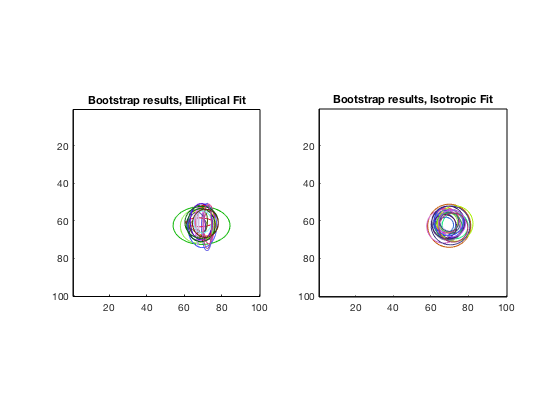

% visualize the parameter estimates
figure; subplot(1,2,1); hold on;
for p=1:size(resultsBOOTElliptical.params,1)
  pp = resultsBOOTElliptical.params(p,:);
  h = drawellipse(pp(2),pp(1),0,2*pp(3)*pp(5),2*pp(3)/pp(5));
  set(h,'Color',rand(1,3));
end
drawrectangle((1+res)/2,(1+res)/2,res,res,'k-');
axis([.5 res+.5 .5 res+.5]);
set(gca,'YDir','reverse');
axis square;
title('Bootstrap results, Elliptical Fit');

% Compare to the non-elliptical fit
subplot(1,2,2); hold on;
for p=1:size(resultsBOOTIsotropic.params,1)
  pp = resultsBOOTIsotropic.params(p,:);
  h = drawellipse(pp(2),pp(1),0,2*pp(3),2*pp(3));
  set(h,'Color',rand(1,3));
end
drawrectangle((1+res)/2,(1+res)/2,res,res,'k-');
axis([.5 res+.5 .5 res+.5]);
set(gca,'YDir','reverse');
axis square;
title('Bootstrap results, Isotropic Fit');

## Example of how to simulate model responses

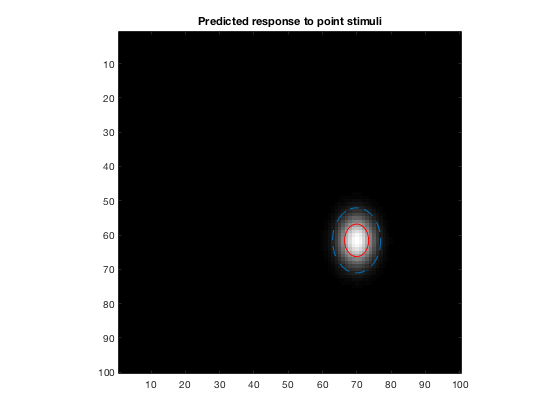

% let's take the model fitted to the full dataset and compute
% the predicted response of the model to some new stimuli.

% let's compute the response of the model to a point stimulus
% that is positioned at different locations in the visual field.
resp = zeros(res,res);
for r=1:res
  for c=1:res
    stim0 = zeros(res,res);
    stim0(r,c) = 1;
    resp(r,c) = modelfunElliptical(resultsElliptical.params,flatten(stim0));
  end
end

% visualize the results
figure; 
mx = max(resp(:));
imagesc(resp,[0 mx]);


axis image tight;
colormap(gray);
title('Predicted response to point stimuli');

hold on
pp = resultsElliptical.params;
h = drawellipse(pp(2),pp(1),0,pp(3)*pp(5),pp(3)/pp(5));
h = drawellipse(pp(2),pp(1),0,2*pp(3)*pp(5),2*pp(3)/pp(5), [], [], '--');

% notice that the results return the pRF.